# Compute Quintic Trajectory for 2-D Planar Motion

Use the [`quinticpolytraj`](docid:robotics_ref.mw_e126a472-347c-4b6f-9c00-b593b7c66124) function with a given set of 2-D *xy* waypoints. Time points for the waypoints are also given.

wpts = [90 140 145; 
        -143 -123 -20]; % x y
theta = [0 pi/4 pi/2];
tEnd = 10;
tpts = linspace(0, tEnd, size(wpts,2));

Specify a time vector for sampling the trajectory. Sample at a smaller interval than the specified time points.

tvec = 0 : 0.1 : tEnd;

Compute the quintic trajectory. The function outputs the trajectory positions (`q`), velocity (`qd`), acceleration (`qdd`), and polynomial coefficients (`pp`) of the quintic polynomial.

[q, qd, qdd, pp] = cubicpolytraj(wpts, tpts, tvec);

Plot the quintic trajectories for the *x- *and *y*-positions. Compare the trjactory with each waypoint.

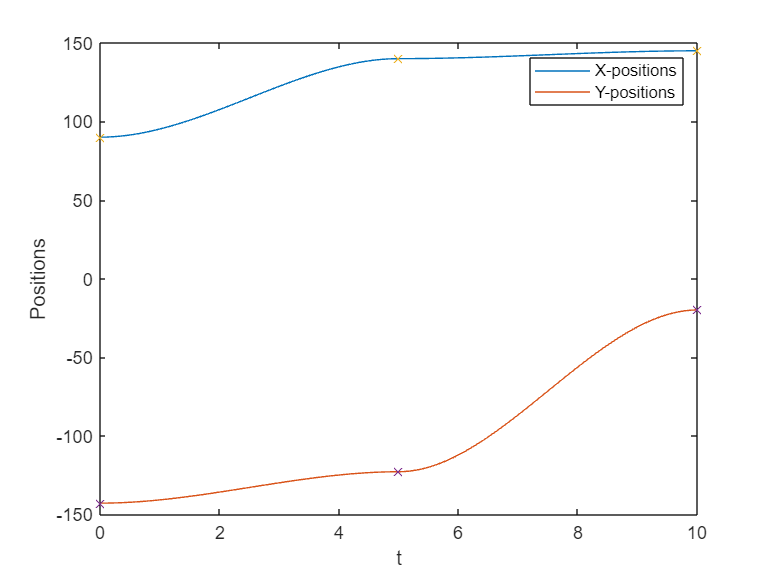

plot(tvec, q)
hold all
plot(tpts, wpts, 'x')
xlabel('t')
ylabel('Positions')
legend('X-positions','Y-positions')
hold off

You can also verify the actual positions in the 2-D plane. Plot the separate rows of the `q` vector and the waypoints as *x-* and *y- *positions.

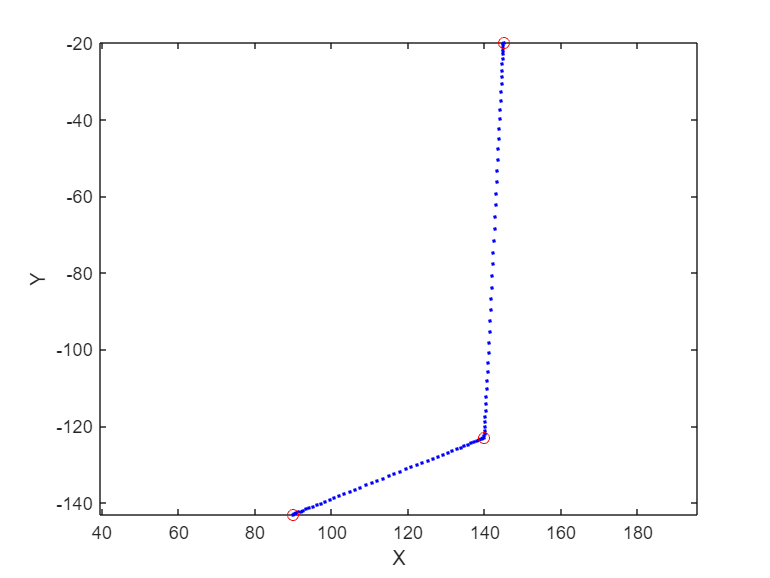

figure
plot(q(1,:),q(2,:),'.b',wpts(1,:),wpts(2,:),'or')
xlabel('X')
ylabel('Y')
axis equal